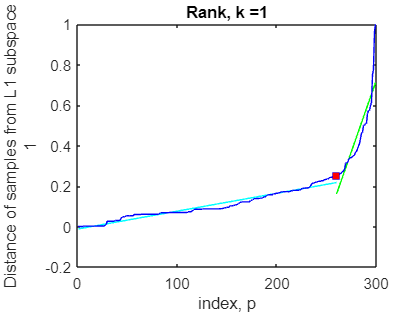

j = [1];
figure

splitfolder=strcat('split',num2str(j));
per =0;%[50,40,30,20,10,5,2,0];
percent = per;
cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering
cd (splitfolder)

folder=strcat('per',num2str(percent));
cd (folder)
my_file = strcat('cell_sample_misclass_per_',num2str(percent),'.csv');
File=readmatrix(my_file,"NumHeaderLines",1);

benign=File(File(:,10)==2,1:9);
T_benign=benign.';
malignant=File(File(:,10)==4,1:9);
T_malignant=malignant.';

% folder_l1=strcat('ACE_dist_3optrank_angle_l1pca_per',num2str(percent));
% mkdir (folder_l1)

ranks=1; [1,2,3];

error_benign = nan(size(ranks));
numbenign=length(T_benign);
Dist_mat_benign_array=nan(length(ranks),numbenign);
threshold_rank_b=nan(size(ranks));
elbow_indx_rank_b=nan(size(ranks));

 i = ranks;
    %fprintf("Rank is %i \n", i) %i);
    cd C:\Users\shukl\Documents\GitHub\CancerAceFiltering\

    T_benign_temp=T_benign;
    Dist_mat_benign=[];


    BF_benign=l1pca_BF(T_benign,i,1,10,10,'');
    for k = 1 : numbenign
        A=T_benign(:,k);
        Dist_mat_benign(k)=norm((A-(BF_benign*BF_benign.'*A)),1);
        k;
    end

    min_val=min(Dist_mat_benign,[],"all");
    max_val=max(Dist_mat_benign,[],"all");
    Dist_mat_benign= Dist_mat_benign-min_val;%]/[max_val-min_val]
    Dist_mat_benign=Dist_mat_benign /(max_val-min_val);


    Dist_mat_benign_array(i,:)=Dist_mat_benign;
    [Dist_mat_benign_asc,Indx_b]=sort(Dist_mat_benign,"ascend");

    y = Dist_mat_benign_asc(:);

    x = (1:length(y))';


    idx = 1:length(x);

    %the code below "unwraps" the repeated regress(y,x) calls.  It's
    %significantly faster than the former for longer y's
    %
    %figure out the m and b (in the y=mx+b sense) for the "left-of-knee"
    sigma_xy = cumsum(x.*y);
    sigma_x  = cumsum(x);
    sigma_y  = cumsum(y);
    sigma_xx = cumsum(x.*x);
    n        = (1:length(y))';
    det = n.*sigma_xx-sigma_x.*sigma_x;
    mfwd = (n.*sigma_xy-sigma_x.*sigma_y)./det;
    bfwd = -(sigma_x.*sigma_xy-sigma_xx.*sigma_y) ./det;

    %figure out the m and b (in the y=mx+b sense) for the "right-of-knee"
    sigma_xy = cumsum(x(end:-1:1).*y(end:-1:1));
    sigma_x  = cumsum(x(end:-1:1));
    sigma_y  = cumsum(y(end:-1:1));
    sigma_xx = cumsum(x(end:-1:1).*x(end:-1:1));
    n        = (1:length(y))';
    det = n.*sigma_xx-sigma_x.*sigma_x;
    mbck = flipud((n.*sigma_xy-sigma_x.*sigma_y)./det);
    bbck = flipud(-(sigma_x.*sigma_xy-sigma_xx.*sigma_y) ./det);

    %figure out the sum of per-point errors for left- and right- of-knee fits

    angle_threshold=nan(size(y));
    error_curve=nan(size(y));
    for breakpt = 2:length(y-1)
        delsfwd = (mfwd(breakpt).*x(1:breakpt)+bfwd(breakpt))-y(1:breakpt);
        delsbck = (mbck(breakpt).*x(breakpt:end)+bbck(breakpt))-y(breakpt:end);
        error_curve(breakpt) = sum(abs(delsfwd))+ sum(abs(delsbck));

        theta=(mfwd(breakpt)-mbck(breakpt))/(1+(mfwd(breakpt)*mbck(breakpt)));
        angle=atan(theta);
        angle_threshold(breakpt)= abs(angle) *180/pi;
    end

    %find location of the min of the error curve
    [~,loc] = min(error_curve);

    x1=x(1:(loc)) ;
    y1=mfwd(loc).* x1 + bfwd(loc);

    x2=x((loc):end);
    y2=mbck(loc).*x2+bbck(loc);


    
    plot(x1,y1,"c")
    hold on
    plot(x2,y2,"g")
    hold on
    angle_x =angle_threshold(loc);% x(loc);
%idx=find(angle_threshold==res_x);
elbow_indx_b =idx(loc);
    
    %             [elbow_b_err_angle,elbow_indx_b]=knee_pt_angle_test((Dist_mat_benign_asc));
    %
    %             error_benign(i)=elbow_b_err_angle;
    %             threshold_rank_b(i)=Dist_mat_benign_asc(elbow_indx_b);
    %             elbow_indx_rank_b(i)=elbow_indx_b;
    %
    %
                
                plot((Dist_mat_benign_asc),'-bs',"MarkerIndices",(elbow_indx_b),'MarkerFaceColor','red','MarkerSize',6 )
                xlabel("index, p")
                ylabel(["Distance of samples from L1 subspace",num2str(i)])
                title(['Rank, k =',num2str(i) ])

                hold off

    %
    %
    %         end
    %
    %
    %         error_benign
    %
    %         [~,optrank_b]= max(error_benign)
    %
    %         Dist_mat_benign_opt=Dist_mat_benign_array(optrank_b,:);
    %         threshold_dist_b= threshold_rank_b(optrank_b);
    %         elbow_indx_b_opt=elbow_indx_rank_b(optrank_b);
    %
    %         ind_O_b=find(Dist_mat_benign_opt>threshold_dist_b);
    %         ind_I_b=find(Dist_mat_benign_opt<=threshold_dist_b);
    %
    %
    %         cluster_b=zeros(size(Dist_mat_benign_opt));
    %         cluster_b(ind_I_b)=1;
    %         figure
    %         y= 1:1:length(benign);
    %         numGroups = length(unique(cluster_b));
    %         gscatter(y,Dist_mat_benign_opt,cluster_b,hsv(numGroups))
    %
    %         figure
    %         plot(sort(Dist_mat_benign_opt,"ascend"),'-s',"MarkerIndices",(elbow_indx_b_opt),'MarkerFaceColor','red','MarkerSize',10 )
    %         xlabel("index")
    %         ylabel(["Distance Benign Asc for opt rank" ,num2str(optrank_b)])
    %         title(['Rank opt for Benign =',num2str(optrank_b),"Split=",num2str(j)])
    %         ind_O_b;
    %
    %
    %         T_benign_temp(:,ind_O_b)=[];
    %         length(T_benign_temp);
    %
    %         Final_benign=T_benign_temp';
    %         Final_benign(:,10)=2;
    %
    %     end
    %     %
    %
    %    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




